# Bernoulli beam with 1:3 internal resonance

In this example, we consider a cantilever beam with a nonlinear support spring at its free end. The linear part of the stiffness of the support spring is tuned such that 1:3 internal resonance occurs between the first two bending modes.

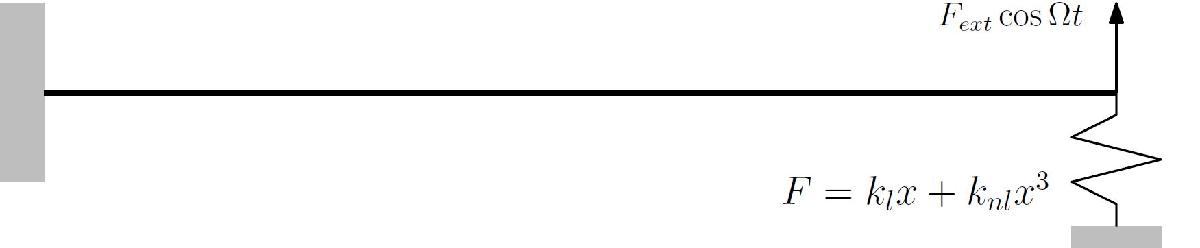

We then extract the forced response curve for both periodic and quasi-periodic response using SSM reduction. In particular, both two- and three-dimensional invariant tori will be computed.

clear all

### Dynamical System Setup

Numerical experiments show that a near 1:3 internal resonance occurs at $k_l=27$. In the following computations, we set the number of beam elements to be 40. The bifurcations observed here are persistent when the number of elements is increased.

nElements = 40;
kLinear = 27;
kNonlinear = 60;
[M,C,K,fnl] = build_model(nElements,kLinear,kNonlinear);

DSorder = 2;
DS = DynamicalSystem(DSorder);
set(DS,'M',M,'C',C,'K',K,'fnl',fnl);
set(DS.Options,'Emax',10,'Nmax',10,'notation','multiindex','RayleighDamp',false)

### Linear Modal analysis

[V,D,W] = DS.linear_spectral_analysis();


 The first 10 eigenvalues are given as 
   1.0e+02 *

  -0.0000 + 0.1560i
  -0.0000 - 0.1560i
  -0.0002 + 0.4658i
  -0.0002 - 0.4658i
  -0.0019 + 1.2377i
  -0.0019 - 1.2377i
  -0.0072 + 2.4119i
  -0.0072 - 2.4119i
  -0.0198 + 3.9821i
  -0.0198 - 3.9821i



### Add forcing

Excitation of the form $\mathbf{f}=\omega_1^2\mathbf{M}\mathbf{\phi}_1\cos\Omega t$ is applied such that only the first linear mode is activated if damping and nonlinear internal forces are removed.

[vs,om_nat] = eigs(K,M,2,'smallestabs');
om_nat = sqrt(diag(om_nat));
f_0 = (om_nat(1))^2*M*vs(:,1);
epsilon = 0.002;
kappas = [-1; 1];
coeffs = [f_0 f_0]/2;
DS.add_forcing(coeffs, kappas, epsilon);

### SSM Computation

% *Choose master spectral subspace*
S = SSM(DS);
set(S.Options, 'reltol', 0.1,'notation','multiindex')

resonant_modes = [1 2 3 4];
mFreq  = [1 3];
order  = 7; % Approximation order
outdof = [2*round(nElements/2)-1; 2*nElements-1];
n = length(M);

### SSM_isol2ep: continuation of equilibrium points

Each equilibrium here corresponds to a periodic orbit of the full system

(near) outer resonance detected for the following combination of master eigenvalues
     0     1     3     0
     2     0     2     0
     0     1     4     1
     1     2     3     0
     2     0     3     1
     3     1     2     0
     5     0     1     0
     0     1     5     2
     0     4     4     0
     1     2     4     1
     2     0     4     2
     2     3     3     0
     3     1     3     1
     4     2     2     0
     5     0     2     1
     6     1     1     0
     8     0     0     0
     0     1     6     3
     0     4     5     1
     1     2     5     2
     1     5     4     0
     2     0     5     3
     2     3     4     1
     3     1     4     2
     3     4     3     0
     4     2     3     1
     5     0     3     2
     5     3     2     0
     6     1     2     1
     7     2     1     0
     8     0     1     1
     9     1     0     0
     0     2     0     2
     1     0     0     3
     0     2     1     3
     0     5     0     1
     1     0    

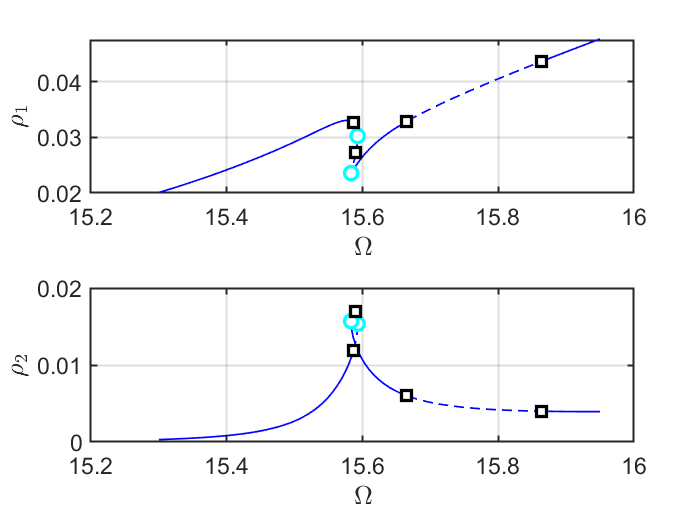

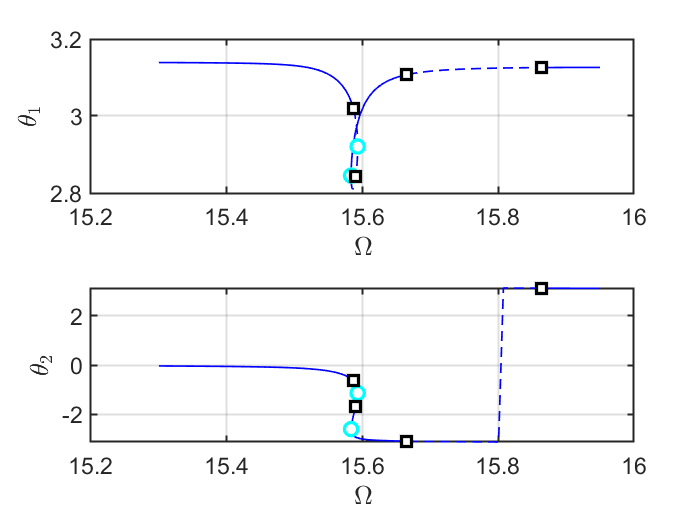

the forcing frequency 1.5300e+01 is nearly resonant with the eigenvalue -1.0306e-03 + i1.5603e+01
the forcing frequency 1.5302e+01 is nearly resonant with the eigenvalue -1.0306e-03 + i1.5603e+01
the forcing frequency 1.5309e+01 is nearly resonant with the eigenvalue -1.0306e-03 + i1.5603e+01
the forcing frequency 1.5316e+01 is nearly resonant with the eigenvalue -1.0306e-03 + i1.5603e+01
the forcing frequency 1.5323e+01 is nearly resonant with the eigenvalue -1.0306e-03 + i1.5603e+01
the forcing frequency 1.5330e+01 is nearly resonant with the eigenvalue -1.0306e-03 + i1.5603e+01
the forcing frequency 1.5337e+01 is nearly resonant with the eigenvalue -1.0306e-03 + i1.5603e+01
the forcing frequency 1.5344e+01 is nearly resonant with the eigenvalue -1.0306e-03 + i1.5603e+01
the forcing frequency 1.5351e+01 is nearly resonant with the eigenvalue -1.0306e-03 + i1.5603e+01
the forcing frequency 1.5358e+01 is nearly resonant with the eigenvalue -1.0306e-03 + i1.5603e+01
the forcing frequenc

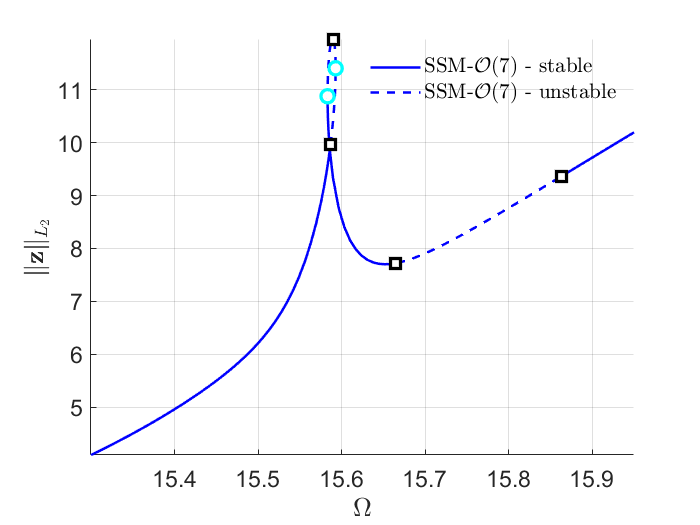

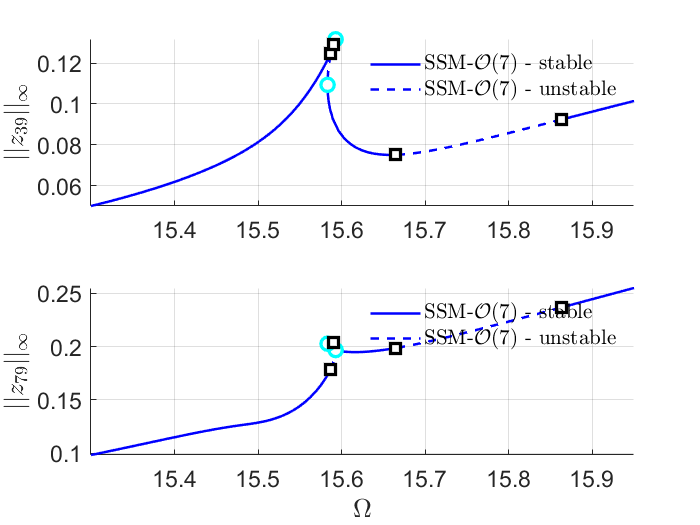

freqRange  = [15.30 15.95];
set(S.FRCOptions, 'SampStyle','cocoBD');                       % sampling style
set(S.FRCOptions, 'nCycle',5000, 'initialSolver', 'fsolve');   % solver for initial solution
set(S.contOptions, 'h_min',1e-3,'h_max',0.01,'NSV',10,'bi_direct',true,'PtMX',100);  % continuation setting
set(S.FRCOptions, 'coordinates', 'cartesian');                 % two representations

isolid = ['isol-',num2str(nElements),'-',num2str(order),'c'];
startep = tic;
FRC = S.SSM_isol2ep(isolid,resonant_modes,order,mFreq,'freq',freqRange,outdof);

timings.epFRC = toc(startep);

### SSM_ep2SN: continuation of SN equilibrium points

Continuation of saddle-node bifurcation of periodic orbits


 Run='SN-40-7c.ep': Continue saddle-node equilibria.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          4.30e-09  2.21e+01    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE            om          eps         Rez1         Rez2         Imz1         Imz2
    0  00:00:00   2.2074e+01      1  EP      1.5593e+01   2.0000e-03  -2.9510e-02   6.3701e-03   6.6270e-03  -1.3980e-02
   10  00:00:00   2.2029e+01      2          1.5561e+01   9.9036e-04  -2.0600e-02  -1.8906e-03   5.6106e-03  -9.7657e-03
   14  00:00:01   2.2027e+01      3  FP      1.5559e+01   9.4686e-04  -1.9689e-02  -3.5754e-03   5.5115e-03  -8.9553e-03
   20  00:00:01   2.2033e+01      4          1.5564e+01   1.1144e-03  -1.9811e-02  -7.2148e-03   5.9151e-03  -8.1084e-03
   30  00:00:01   2.2091e+01      5          1.5604e+01   3.2353e-03  -2.5347e-02  -1.8662e-02   7.2287e-03  -8.2798e-03
   36  0

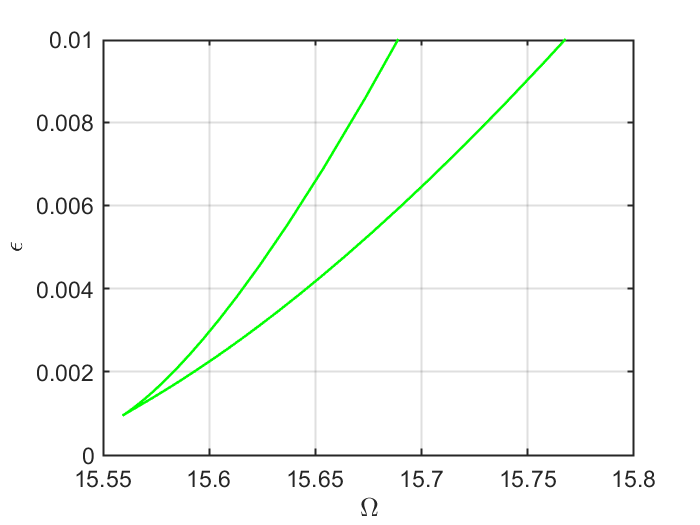

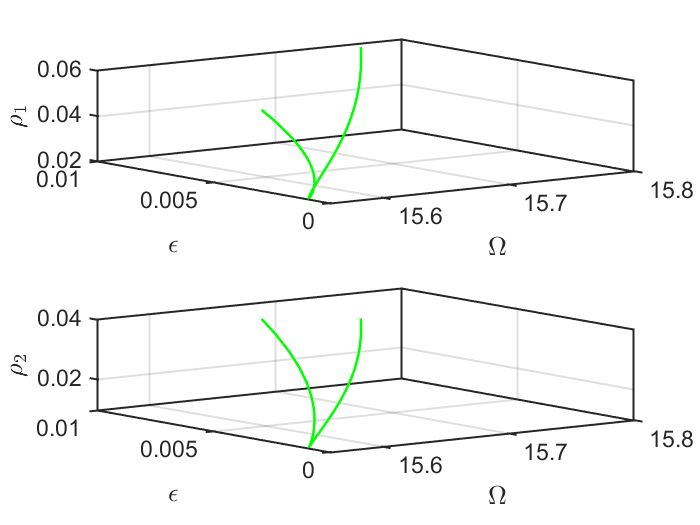

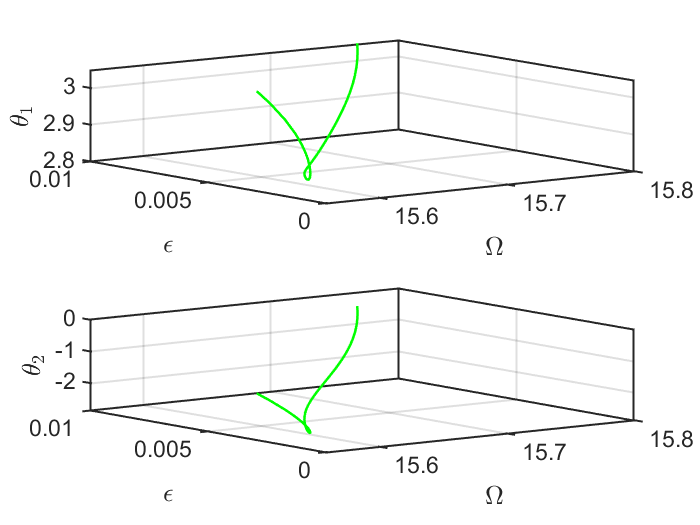

the forcing frequency 1.5689e+01 is nearly resonant with the eigenvalue -1.0306e-03 + i1.5603e+01
the forcing frequency 1.5673e+01 is nearly resonant with the eigenvalue -1.0306e-03 + i1.5603e+01
the forcing frequency 1.5654e+01 is nearly resonant with the eigenvalue -1.0306e-03 + i1.5603e+01
the forcing frequency 1.5637e+01 is nearly resonant with the eigenvalue -1.0306e-03 + i1.5603e+01
the forcing frequency 1.5623e+01 is nearly resonant with the eigenvalue -1.0306e-03 + i1.5603e+01
the forcing frequency 1.5613e+01 is nearly resonant with the eigenvalue -1.0306e-03 + i1.5603e+01
the forcing frequency 1.5604e+01 is nearly resonant with the eigenvalue -1.0306e-03 + i1.5603e+01
the forcing frequency 1.5597e+01 is nearly resonant with the eigenvalue -1.0306e-03 + i1.5603e+01
the forcing frequency 1.5591e+01 is nearly resonant with the eigenvalue -1.0306e-03 + i1.5603e+01
the forcing frequency 1.5585e+01 is nearly resonant with the eigenvalue -1.0306e-03 + i1.5603e+01
the forcing frequenc

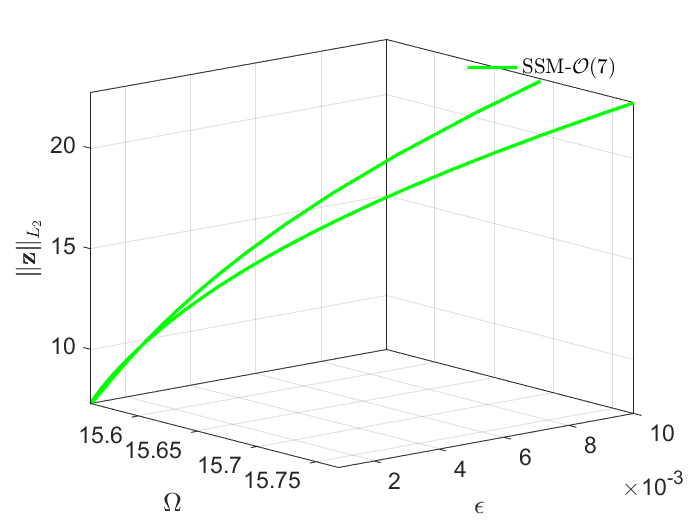

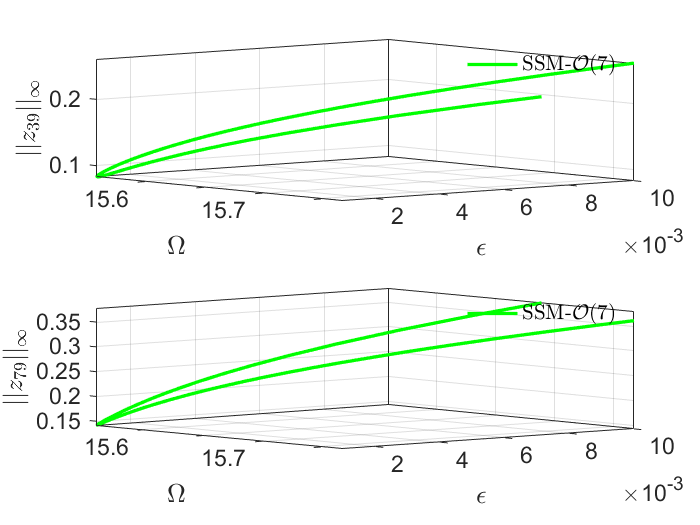

set(S.contOptions, 'h_min',1e-3,'h_max',0.1);              % continuation setting
epsRange = [1e-4 1e-2];
bd    = coco_bd_read([isolid,'.ep']);
omega = coco_bd_col(bd,'om');
SNlab = coco_bd_labs(bd,'SN');
if ~isempty(SNlab)
    % find the lab with smallest omega
    SNidx = coco_bd_idxs(bd,'SN');
    omSN  = omega(SNidx);
    [~,id]= max(omSN);
    SNlab = SNlab(id);
    SNid = ['SN-',num2str(nElements),'-',num2str(order),'c'];
    S.SSM_ep2SN(SNid,isolid,SNlab,{freqRange,epsRange},outdof);
end

### SSM_ep2HB: continuation of HB equilibrium points

Continuation of Hopf bifurcation of periodic orbits


 Run='HB1-40-7c.ep': Continue Hopf equilibria.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          3.45e-09  2.22e+01    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE            om          eps         Rez1         Rez2         Imz1         Imz2
    0  00:00:00   2.2177e+01      1  EP      1.5665e+01   2.0000e-03  -3.2831e-02  -6.0116e-03   1.1299e-03  -2.1552e-04
   10  00:00:01   2.2081e+01      2          1.5597e+01   5.2426e-04  -1.9854e-02  -1.8619e-03   5.6412e-04  -1.9735e-04
   20  00:00:01   2.2068e+01      3          1.5588e+01   3.7197e-04  -1.7116e-02  -1.2255e-03   4.3179e-04  -1.4786e-04
   21  00:00:01   2.2068e+01      4  FP      1.5588e+01   3.7136e-04  -1.7106e-02  -1.2227e-03   4.3124e-04  -1.4744e-04
   30  00:00:02   2.2089e+01      5          1.5603e+01   3.9645e-04  -1.8664e-02  -1.2761e-03   4.5826e-04  -1.0621e-04
   40  00:00:0

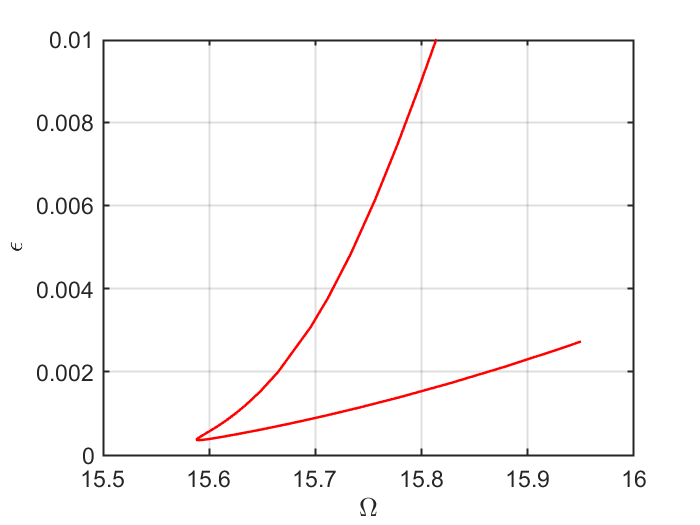

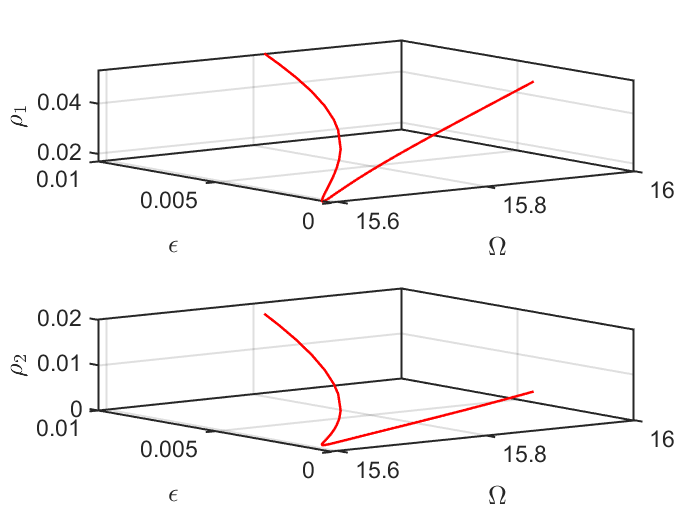

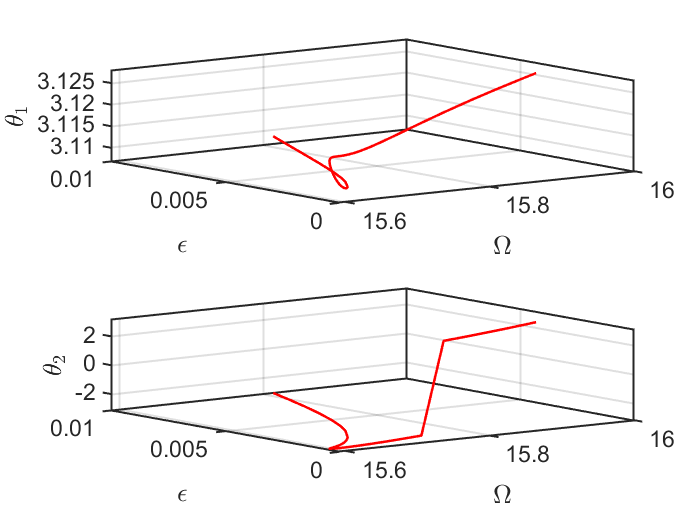

the forcing frequency 1.5950e+01 is nearly resonant with the eigenvalue -1.0306e-03 + i1.5603e+01
the forcing frequency 1.5926e+01 is nearly resonant with the eigenvalue -1.0306e-03 + i1.5603e+01
the forcing frequency 1.5878e+01 is nearly resonant with the eigenvalue -1.0306e-03 + i1.5603e+01
the forcing frequency 1.5827e+01 is nearly resonant with the eigenvalue -1.0306e-03 + i1.5603e+01
the forcing frequency 1.5779e+01 is nearly resonant with the eigenvalue -1.0306e-03 + i1.5603e+01
the forcing frequency 1.5740e+01 is nearly resonant with the eigenvalue -1.0306e-03 + i1.5603e+01
the forcing frequency 1.5711e+01 is nearly resonant with the eigenvalue -1.0306e-03 + i1.5603e+01
the forcing frequency 1.5689e+01 is nearly resonant with the eigenvalue -1.0306e-03 + i1.5603e+01
the forcing frequency 1.5673e+01 is nearly resonant with the eigenvalue -1.0306e-03 + i1.5603e+01
the forcing frequency 1.5660e+01 is nearly resonant with the eigenvalue -1.0306e-03 + i1.5603e+01
the forcing frequenc

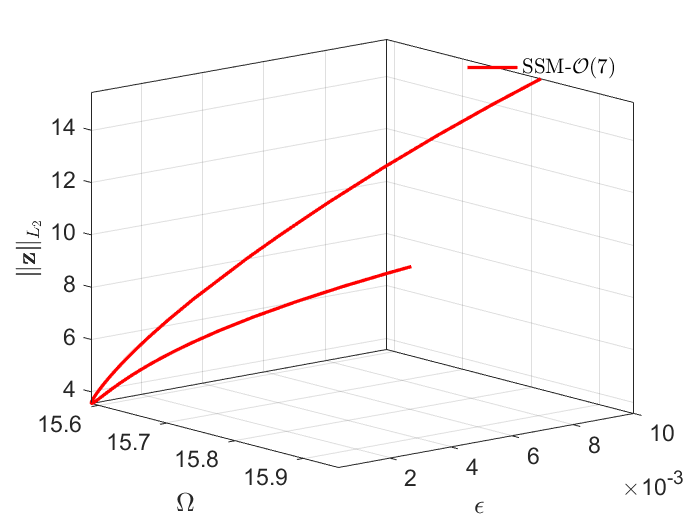

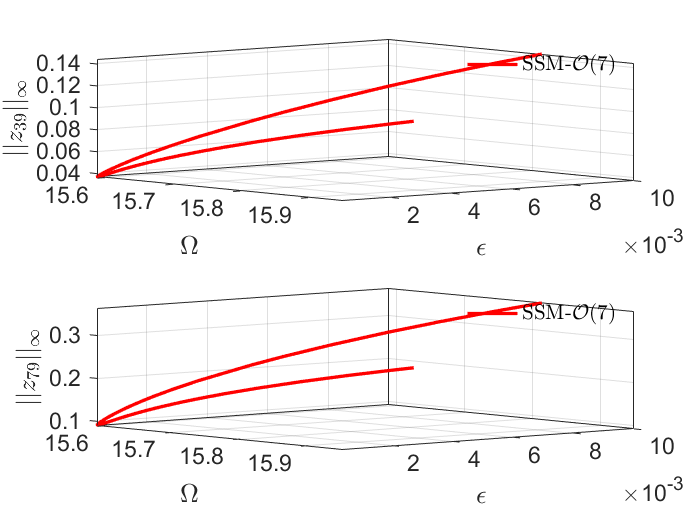

HBlab = coco_bd_labs(bd,'HB');
% find the lab with smallest omega
HBidx = coco_bd_idxs(bd,'HB');
omHB  = omega(HBidx);
[~,idx] = sort(omHB);
HBlab1 = HBlab(idx(end-1));
HBid1 = ['HB1-',num2str(nElements),'-',num2str(order),'c'];
S.SSM_ep2HB(HBid1,isolid,HBlab1,{freqRange,epsRange},outdof);

Continuation of HB points with the other one as starting point


 Run='HB2-40-7c.ep': Continue Hopf equilibria.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          4.54e-08  2.21e+01    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE            om          eps         Rez1         Rez2         Imz1         Imz2
    0  00:00:00   2.2078e+01      1  EP      1.5590e+01   2.0000e-03  -2.6008e-02  -1.7629e-03   8.0273e-03  -1.6839e-02
   10  00:00:00   2.2054e+01      2          1.5575e+01   1.4240e-03  -2.5057e-02   2.3221e-03   6.3371e-03  -1.2466e-02
   20  00:00:01   2.2051e+01      3  FP      1.5573e+01   1.3727e-03  -2.5879e-02   4.6803e-03   5.4330e-03  -1.0510e-02
   20  00:00:01   2.2052e+01      4          1.5573e+01   1.3734e-03  -2.5905e-02   4.7216e-03   5.4178e-03  -1.0477e-02
   30  00:00:02   2.2069e+01      5          1.5582e+01   1.7779e-03  -3.0614e-02   8.5210e-03   4.2171e-03  -7.7109e-03
   40  00:00:0

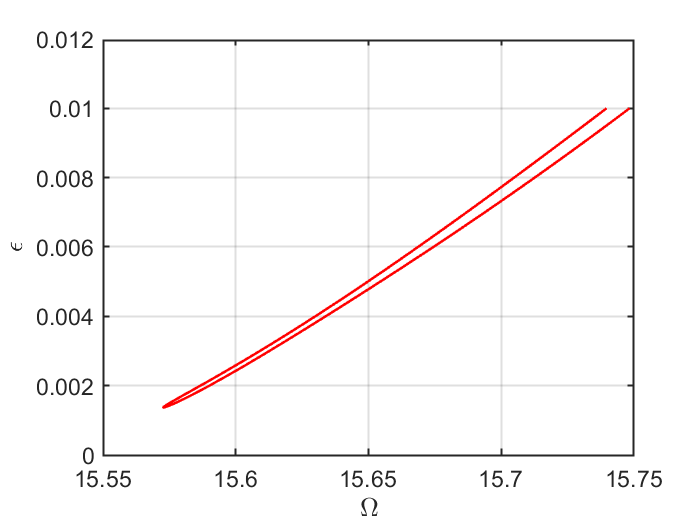

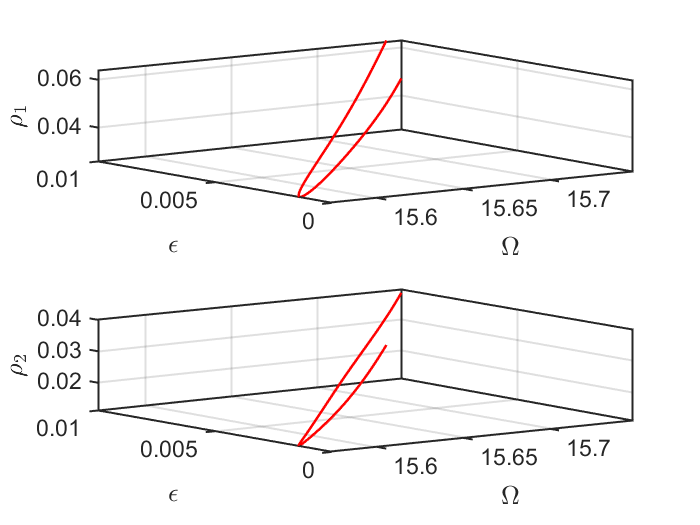

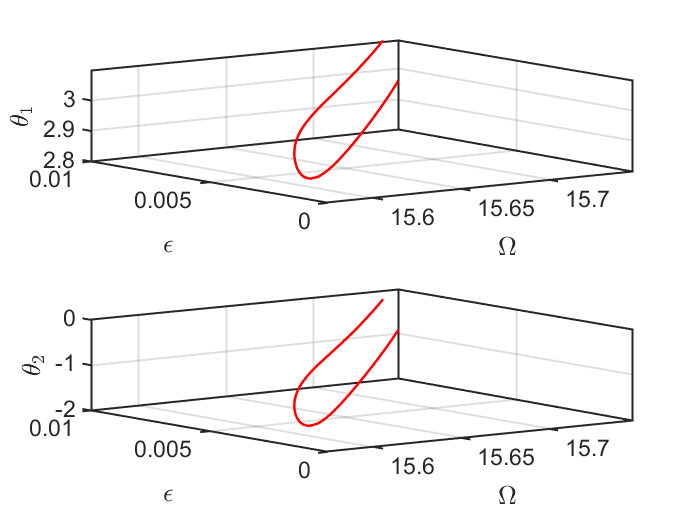

the forcing frequency 1.5740e+01 is nearly resonant with the eigenvalue -1.0306e-03 + i1.5603e+01
the forcing frequency 1.5736e+01 is nearly resonant with the eigenvalue -1.0306e-03 + i1.5603e+01
the forcing frequency 1.5732e+01 is nearly resonant with the eigenvalue -1.0306e-03 + i1.5603e+01
the forcing frequency 1.5728e+01 is nearly resonant with the eigenvalue -1.0306e-03 + i1.5603e+01
the forcing frequency 1.5724e+01 is nearly resonant with the eigenvalue -1.0306e-03 + i1.5603e+01
the forcing frequency 1.5720e+01 is nearly resonant with the eigenvalue -1.0306e-03 + i1.5603e+01
the forcing frequency 1.5716e+01 is nearly resonant with the eigenvalue -1.0306e-03 + i1.5603e+01
the forcing frequency 1.5712e+01 is nearly resonant with the eigenvalue -1.0306e-03 + i1.5603e+01
the forcing frequency 1.5708e+01 is nearly resonant with the eigenvalue -1.0306e-03 + i1.5603e+01
the forcing frequency 1.5704e+01 is nearly resonant with the eigenvalue -1.0306e-03 + i1.5603e+01
the forcing frequenc

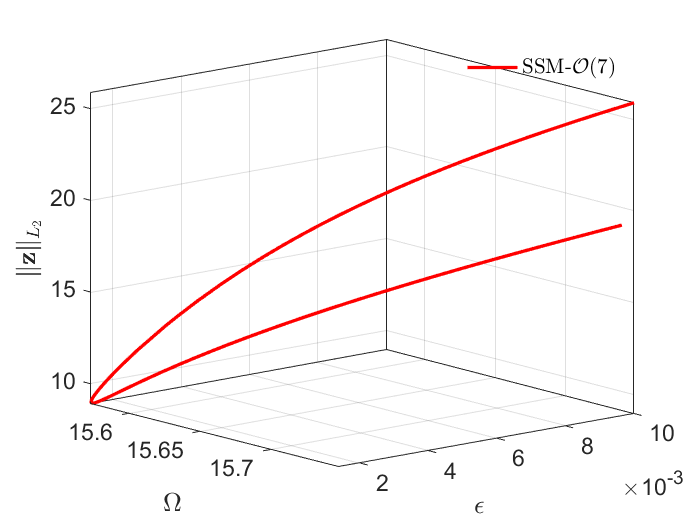

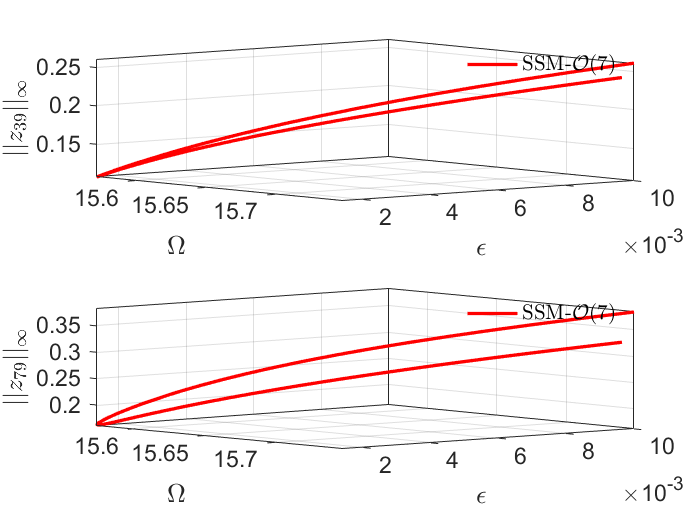

HBid2 = ['HB2-',num2str(nElements),'-',num2str(order),'c'];
S.SSM_ep2HB(HBid2,isolid,HBlab(idx(2)),{freqRange,epsRange},outdof);

### SSM_HB2po: continuation of periodic orbits from HB point 


 Run='po1-40-7c.po': Continue periodic orbits born from HB point.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          3.05e-05  3.50e+01    0.0    0.0    0.0
   1   1  1.00e+00  1.55e-03  2.48e-06  3.50e+01    0.0    0.0    0.0
   2   1  1.00e+00  1.20e-03  1.49e-06  3.50e+01    0.0    0.0    0.0
   3   1  1.00e+00  7.68e-04  6.08e-07  3.50e+01    0.0    0.0    0.0
   4   1  1.00e+00  4.70e-04  2.27e-07  3.50e+01    0.0    0.0    0.0
   5   1  1.00e+00  2.47e-04  6.25e-08  3.50e+01    0.0    0.0    0.0
   6   1  1.00e+00  8.65e-05  7.70e-09  3.50e+01    0.0    0.1    0.0
   7   1  1.00e+00  1.14e-05  1.34e-10  3.50e+01    0.0    0.1    0.0
   8   1  1.00e+00  1.94e-07  3.85e-14  3.50e+01    0.0    0.1    0.0

 STEP      TIME        ||U||  LABEL  TYPE            om    po.period          eps
    0  00:00:00   3.4959e+01      1  EP      1.5665e+01   1.9122e+01   2.0000e-

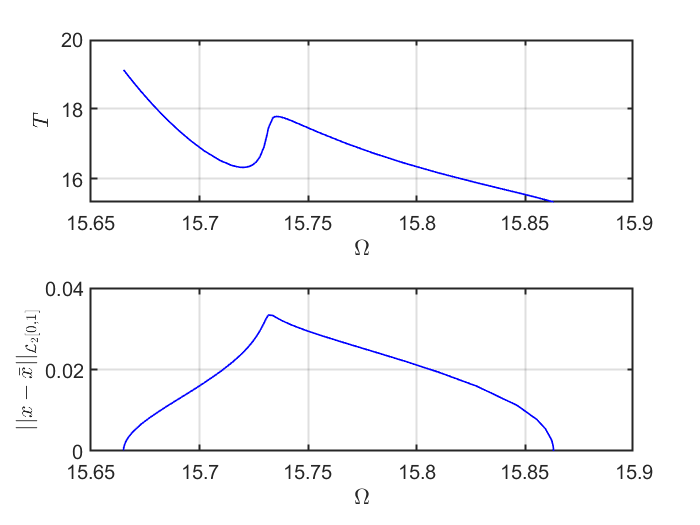

Constructing torus in reduced dynamical system
Interpolation at frequency 1.566497e+01
Interpolation at frequency 1.566498e+01
Interpolation at frequency 1.566499e+01
Interpolation at frequency 1.566499e+01
Interpolation at frequency 1.566500e+01
Interpolation at frequency 1.566502e+01
Interpolation at frequency 1.566504e+01
Interpolation at frequency 1.566508e+01
Interpolation at frequency 1.566516e+01
Interpolation at frequency 1.566531e+01
Interpolation at frequency 1.566560e+01
Interpolation at frequency 1.566614e+01
Interpolation at frequency 1.566720e+01
Interpolation at frequency 1.566924e+01
Interpolation at frequency 1.567302e+01
Interpolation at frequency 1.567701e+01
Interpolation at frequency 1.568125e+01
Interpolation at frequency 1.568577e+01
Interpolation at frequency 1.569065e+01
Interpolation at frequency 1.569599e+01
Interpolation at frequency 1.570206e+01
Interpolation at frequency 1.570956e+01
Interpolation at frequency 1.571502e+01
Interpolation at frequency 1.5718

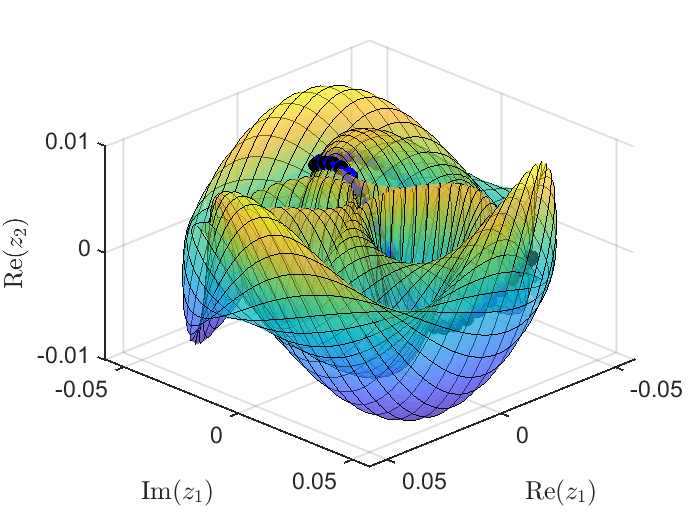

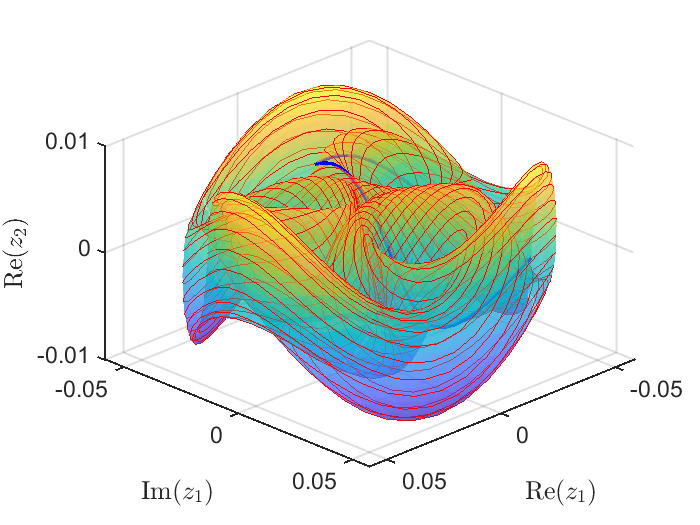


 FRCs from ='po1-40-7c.po': generating torus in physical domain.


set(S.contOptions, 'h_max',0.3,'PtMX',100, 'bi_direct', false, 'NSV', 1,'NAdapt',5);                    % continuation setting
po1id = ['po1-',num2str(nElements),'-',num2str(order),'c'];
startpo = tic;
set(S.FRCOptions,'parSamps',15.75);
S.SSM_HB2po(po1id,isolid,HBlab1,'freq',freqRange,[outdof; outdof+n],'saveICs');

timings.po1FRC = toc(startpo);

Continuation of periodic orbits from another HB point


 Run='po2-40-7c.po': Continue periodic orbits born from HB point.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          3.78e-05  2.95e+01    0.0    0.0    0.0
   1   1  1.00e+00  6.43e-04  3.69e-07  2.95e+01    0.0    0.0    0.0
   2   2  5.00e-01  1.37e-03  5.83e-07  2.95e+01    0.0    0.0    0.0
   3   1  1.00e+00  9.77e-04  8.20e-07  2.95e+01    0.0    0.0    0.0
   4   1  1.00e+00  3.24e-04  9.03e-08  2.95e+01    0.0    0.0    0.0
   5   1  1.00e+00  6.82e-05  4.00e-09  2.95e+01    0.0    0.0    0.0
   6   1  1.00e+00  2.37e-06  4.84e-12  2.95e+01    0.0    0.0    0.0
   7   1  1.00e+00  3.08e-09  8.11e-16  2.95e+01    0.0    0.1    0.0

 STEP      TIME        ||U||  LABEL  TYPE            om    po.period          eps
    0  00:00:00   2.9541e+01      1  EP      1.5590e+01   1.3902e+01   2.0000e-03
    2  00:00:00   2.9540e+01      2          1.5590e+01   1.3901e+0

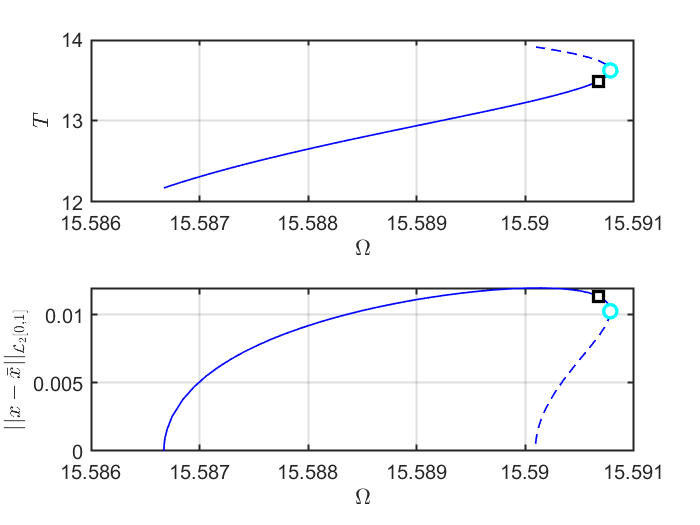

Constructing torus in reduced dynamical system
Interpolation at frequency 1.559009e+01
Interpolation at frequency 1.559010e+01
Interpolation at frequency 1.559011e+01
Interpolation at frequency 1.559012e+01
Interpolation at frequency 1.559013e+01
Interpolation at frequency 1.559016e+01
Interpolation at frequency 1.559022e+01
Interpolation at frequency 1.559035e+01
Interpolation at frequency 1.559050e+01
Interpolation at frequency 1.559059e+01
Interpolation at frequency 1.559074e+01
Interpolation at frequency 1.559078e+01
Interpolation at frequency 1.559078e+01
Interpolation at frequency 1.559078e+01
Interpolation at frequency 1.559072e+01
Interpolation at frequency 1.559067e+01
Interpolation at frequency 1.559059e+01
Interpolation at frequency 1.559050e+01
Interpolation at frequency 1.559039e+01
Interpolation at frequency 1.559014e+01
Interpolation at frequency 1.558987e+01
Interpolation at frequency 1.558957e+01
Interpolation at frequency 1.558927e+01
Interpolation at frequency 1.5589

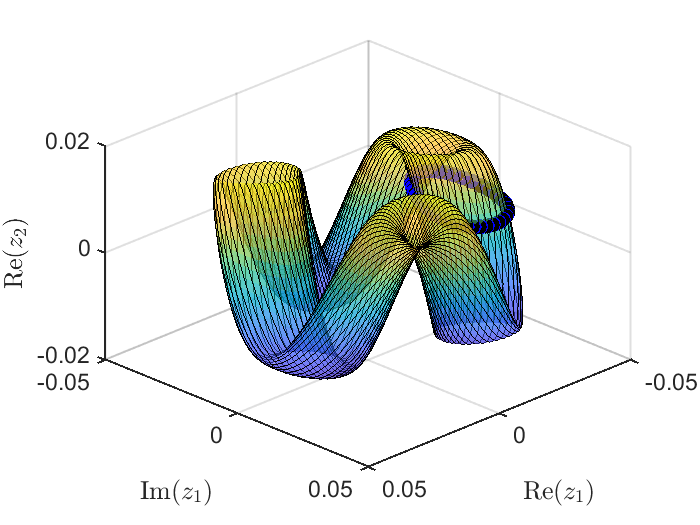

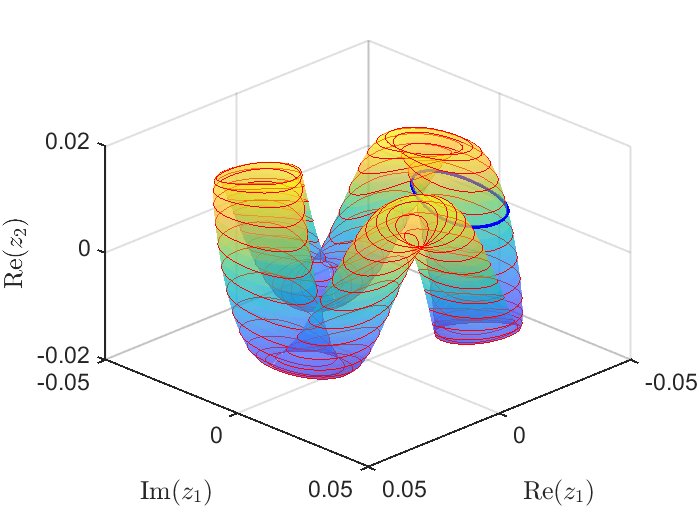


 FRCs from ='po2-40-7c.po': generating torus in physical domain.


HBlab2 = HBlab(idx(2));
po2id = ['po2-',num2str(nElements),'-',num2str(order),'c'];
set(S.contOptions, 'h_max',0.05, 'PtMX', 70, 'NSV', 2, 'bi_direct', false, 'NAdapt', 10);              % continuation setting
startpo = tic;
set(S.FRCOptions,'parSamps',[15.589, 15.5905]);
S.SSM_HB2po(po2id,isolid,HBlab2,'freq',freqRange,[outdof; outdof+n],'saveICs');

timings.po2FRC = toc(startpo);

###  SSM_po2TR: continuation of TR bifurcation periodic orbits

Continuation of quasi-periodic Hopf bifurcation of two-dimensional invairant tori


 Run='TR-40-7c.po': Continue TR periodic orbits from label 16 of run po2-40-7c.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          2.80e-07  3.08e+01    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE            om          eps    po.period
    0  00:00:00   3.0766e+01      1  EP      1.5591e+01   2.0000e-03   1.3484e+01
    2  00:00:00   3.0912e+01      2          1.5589e+01   1.9535e-03   1.3676e+01
    4  00:00:01   3.1269e+01      3          1.5587e+01   1.8479e-03   1.4139e+01
    6  00:00:02   3.2110e+01      4          1.5581e+01   1.6366e-03   1.5201e+01
    8  00:00:03   3.2684e+01      5          1.5578e+01   1.5145e-03   1.5917e+01
   10  00:00:04   3.2909e+01      6          1.5576e+01   1.4694e-03   1.6205e+01
   12  00:00:06   3.3027e+01      7          1.5576e+01   1.4454e-03   1.6364e+01
   14  00:00:07   3.3093e+01      8          1.5575

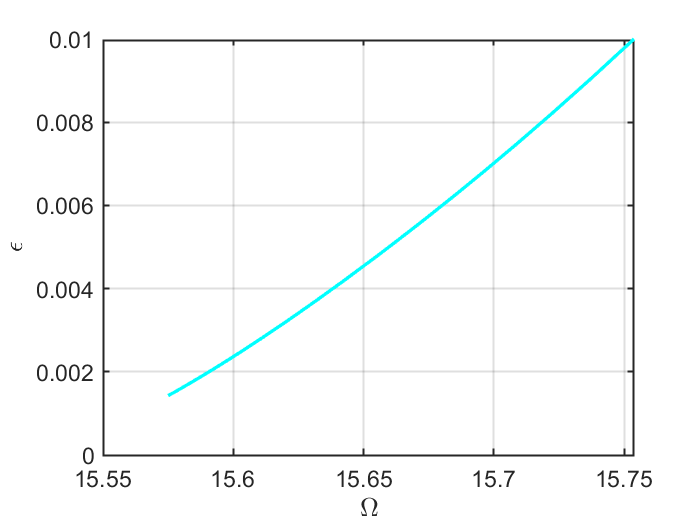

Constructing torus in reduced dynamical system
Interpolation at frequency 1.557500e+01
Interpolation at frequency 1.557500e+01
Interpolation at frequency 1.557500e+01
Interpolation at frequency 1.557501e+01
Interpolation at frequency 1.557502e+01
Interpolation at frequency 1.557504e+01
Interpolation at frequency 1.557504e+01
Interpolation at frequency 1.557505e+01
Interpolation at frequency 1.557506e+01
Interpolation at frequency 1.557507e+01
Interpolation at frequency 1.557508e+01
Interpolation at frequency 1.557509e+01
Interpolation at frequency 1.557509e+01
Interpolation at frequency 1.557510e+01
Interpolation at frequency 1.557511e+01
Interpolation at frequency 1.557513e+01
Interpolation at frequency 1.557554e+01
Interpolation at frequency 1.557623e+01
Interpolation at frequency 1.557751e+01
Interpolation at frequency 1.558091e+01
Interpolation at frequency 1.558665e+01
Interpolation at frequency 1.558945e+01
Interpolation at frequency 1.559067e+01
Interpolation at frequency 1.5590

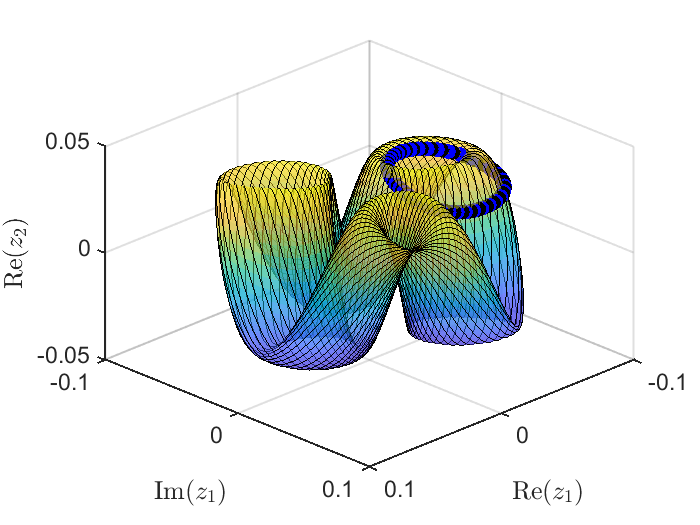

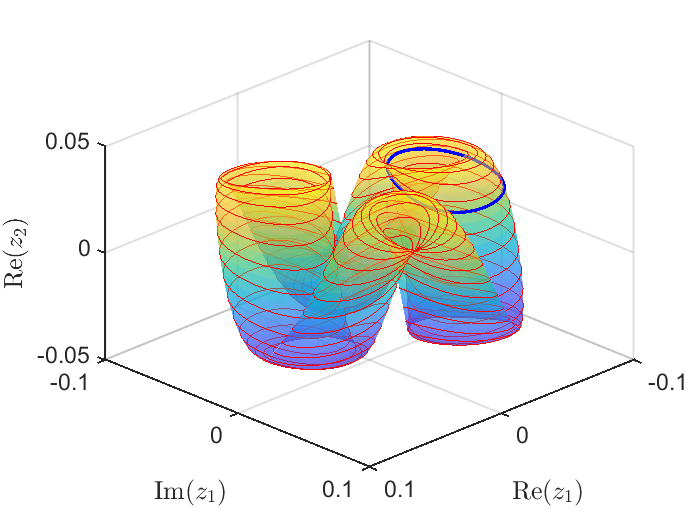


 FRCs from ='TR-40-7c.po': generating torus in physical domain.


bd    = coco_bd_read([po2id,'.po']);
TRlab = coco_bd_labs(bd,'TR');
assert(~isempty(TRlab), 'No TR periodic orbits are found');
set(S.contOptions, 'h_max',1, 'bi_direct', true, 'NAdapt', 0);              % continuation setting
TRid = ['TR-',num2str(nElements),'-',num2str(order),'c'];
S.SSM_po2TR(TRid,po2id,TRlab,{freqRange,epsRange},[outdof; outdof+n]);

### SSM_TR2tor: continuation of tori from TR point

Continuation of three-dimensional invariant tori


 Run='tor-40-7c.tor': Continue tori born from TR point.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          3.62e-06  1.16e+02    0.0    0.0    0.0
   1   1  1.00e+00  2.98e-05  2.90e-10  1.16e+02    0.1    0.3    0.0
   2   1  1.00e+00  3.78e-04  2.95e-08  1.16e+02    0.1    0.5    0.1
   3   1  1.00e+00  4.23e-05  3.69e-10  1.16e+02    0.1    0.8    0.1
   4   1  1.00e+00  7.52e-06  1.16e-11  1.16e+02    0.1    1.1    0.2
   5   1  1.00e+00  3.41e-08  2.90e-15  1.16e+02    0.2    1.3    0.2

 STEP      TIME        ||U||  LABEL  TYPE            om       varrho          om1          om2          eps
    0  00:00:02   1.1586e+02      1  EP      1.5591e+01   5.0340e-03   2.3458e-03   4.6599e-01   2.0000e-03
    2  00:00:21   1.1586e+02      2  BP      1.5591e+01   5.0336e-03   2.3456e-03   4.6599e-01   2.0000e-03
    5  00:00:27   1.1586e+02      3          1.5591e+01  

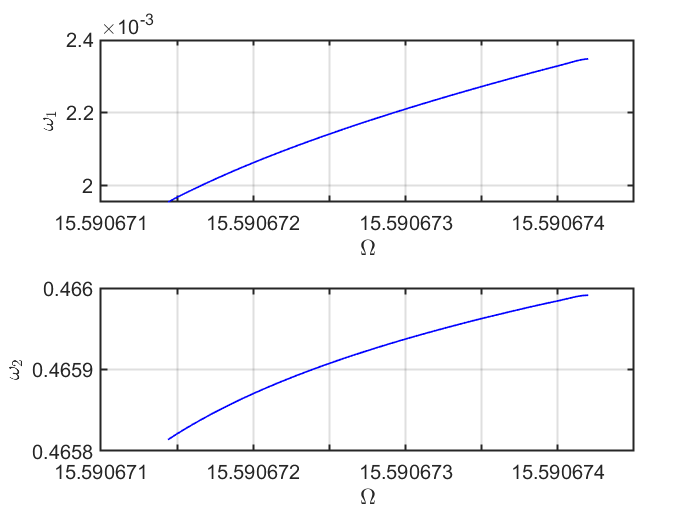

Constructing 3D torus in reduced dynamical system
Interpolation at frequency 1.559067e+01
Interpolation at frequency 1.559067e+01
Interpolation at frequency 1.559067e+01
Interpolation at frequency 1.559067e+01
Interpolation at frequency 1.559067e+01
Interpolation at frequency 1.559067e+01
Interpolation at frequency 1.559067e+01
Interpolation at frequency 1.559067e+01
Interpolation at frequency 1.559067e+01
Interpolation at frequency 1.559067e+01
Interpolation at frequency 1.559067e+01
Interpolation at frequency 1.559067e+01

 FRCs from ='tor-40-7c.tor': generating torus in physical domain.


TRlab = 1; %
set(S.contOptions, 'h_max',100,'PtMX',50,'bi_direct',false,'NSV', 5);              % continuation setting
set(S.FRCOptions,"torNumSegs",15); %2*15+1=31 segments
torid = ['tor-',num2str(nElements),'-',num2str(order),'c'];
starttor = tic;
S.SSM_TR2tor(torid,TRid,TRlab,'freq',freqRange,[outdof; outdof+n],'saveICs');

timings.torFRC = toc(starttor); 